%%%% Chapter 4 Uitools

% Uitools is the name given by MathWorks for a set of user-interface functions. 
% These functions have existed in a pretty stable situation for many MATLAB versions, 
%  some as far back as R12 (MATLAB 6.0, released in 2000). 
% Despite this, to this day (MATLAB R2011a), 
%   some of these functions are unsupported and only partially documented. 
% Many important uitools are Java based, 
%   hence the reason for including this chapter in this book. 
% Here, we will only focus on the Java-based or customizable functions. 

% The odd thing about uitools is that some of these functions appear
%   in the category help output (result of help('uitools')), 
%   and in some cases, 
%   they may even have a fully visible help section (e.g., help('setptr')) 
%   but do not have any online help documentation 
%   (docsearch('setptr') fails 
%    and doc('setptr') simply displays the readable help text). 

% In other cases (e.g., help('uitree')), the entire readable help section is as follows: 
%   WARNING: This feature is not supported in MATLAB 
%   and the API and functionality may change in a future release. 
% In such cases, one has to manually edit the function (edit('uitree')) 
%   in order to place a leading comment sign (%) at line 4 
%   in order for the help section to become readable in the Command Window.

% These two phenomena are called "Semi-Documented Functions" in this book,
%   and many other examples will be presented in this and later chapters. 
% All these functions are officially unsupported by MathWorks,
%   even when having a readable help section. 
% The rule of thumb appears to be that a MATLAB function is supported 
%   only if it has online documentation. 
% Note that in some rare cases, 
%   a documentation discrepancy may be due to a MathWorks documentation error, 
%   and not due to unsupportability. 

% The reasons for the partial documentation are varied: 
%   Some functions (such as uitable or uitree) are based on internal Java objects 
%   that MathWorks may feel are still unstable, buggy, 
%   or should be kept under wraps for some reason. 
% Others (such as moveptr) were either developed for internal MATLAB development 
%   and are not yet ready for public use or (like uicontainer) 
%   are not well integrated with other MATLAB functionalities. 
% Whatever be the reasons, the uitools folder, 
%   located at %matlabroot%/toolbox/matlab/uitools/, 
%   contains a treasure trove well worth exploring. 
% Type help('uitools') for an annotated partial list of available uitools 
%   and dir([matlabroot,'\toolbox\matlab\uitools']) for a full (unannotated) list. 

%% 4.1 Uitable

% For many years, the highest-requested MATLAB GUI component 
%   was an editable data table/grid. 
% Such a component was missing both from MATLAB's GUI editor (guide) 
%   and from the supported list of GUI functions until R2008a (aka MATLAB 7.6). 
% This missing component appears, 
%   at least according to the number of requests/queries/posts on the MATLAB forums 
%   and from the number of submissions/downloads of File Exchange solutions, 
%   to be the single most needed missing GUI component in MATLAB. 

% True, there are many possible methods of creating data tables in MATLAB 
%   using basic MATLAB building blocks, 
%   and the variety of solutions on the File Exchange reflects this: 
%   one can use a two-dimensional matrix of editboxes or labels,
%   a standard listbox, ActiveX components, standard Java Swing widgets,
%   undocumented Math Works Java classes, and even text labels on a plot axes.

% Starting with MATLAB 7 (R14),
%   MathWorks have included the unsupported function uitable in the uitools folder. 
% This function uses the internal MATLAB Java widget 
%   com.mathworks.widgets.spreadsheet.SpreadsheetTable, 
%   which derives from the standard Java Swing JTable class via 
%   com.mathworks.mwswing.MJTable.
% uitable became fully supported in R2008a9 after many years in unsupported mode, 
%   and then switched to a com.jidesoft.grid.SortableTable-derived table. 
% uitable provides a lightweight and consistent look-and-feel alternative 
%   to the non-Java solutions and integrates well with MATLAB GUI.
% Use of uitable has the benefit of employing a scrollable JTable 
%   without the hassle of setting up a ScrollableViewport and 
%   other similar nuts and bolts. 
% Also, uitable automatically detects 
%   Boolean (islogical) and Combo-Box (iscell) data columns 
%   and uses corresponding cell editors for them 
%   — checkboxes and dropdowns, respectively. 

% Since R2008a, MATLAB includes both versions of uitable.
% MATLAB automatically selects the version to use based on 
%   the supplied input and output arguments: uitable accepts data and parameters 
%   in the familiar P-V (property-value) named-pair format, 
%   in which case, MATLAB automatically uses the new version of uitable 
%   (we can force it to use the older version by adding a 'vO' input argument). 
% The old (pre-R2008a) uitable also accepts a couple of other formats. 
% In both versions, uitable accepts an optional figure handle 
%   as the leading (first) argument, which is gcf by default. 

% MATLAB automatically uses the new uitable when 
%   only a single output argument (or none) is requested 
%   and when the properties conform to the P-V pairs of the new uitable's properties. 
% In all other cases, the older uitable is used. 

mtable = uitable('Data',magic(3)); % new uitable, no warning 
% [mtable,c] =uitable('vO','Data',magic(3)); % old uitable, warning 

% The new uitable returns only a single argument 
%   — a MATLAB handle of the created table. 
% The new version of uitable is created in a similar manner to the old version: 
mtable=uitable(gcf, 'Data',magic(3), 'ColumnName',{'A', 'B', 'C'}); 
set(mtable, 'Position', [10,10,280,100]);
% The new uitable's data can be retrieved and set much more easily
%   than the old version's by 
%   simply using the Data property (no cell casting is necessary): 
data=get(mtable,'Data')
set(mtable, 'Data', [1,2,3; 4,5,6]); 
set(mtable,'Data',{1,2,3; 4,'text',true}); 

% 4.1.1 Customizing Uitable 
% The MATLAB handles returned by uitable (either the new or the old versions) 
%   have some built-in customizations possible. 
% However, using the underlying Java table reference,
%   we can gain access to a much wider range of customizations, 
%   which shall be discussed below. 
% Note that the table object returned by uitable is not actually a Java object 
%   but rather a MATLAB handle object. 
% Because of this, I call the returned object mtable 
%   and the underlying Java object jtable. 

% In the following listing of Java sub-components, 
%   we shall use the following annotated screenshot of a uitable
%   (the new version — it is pretty similar to the old version): 

% Unfortunately, there is no direct way of getting the new uitable's 
%   underlying jtable reference. 
% However, we can use the findjobj utility for this (see Section 7.2.2).
% The following code snippet shows how we "dig out" jtable 
%   from its containing scrollpane: 
mtable = uitable('Data',magic(3));
jscroll = findjobj(mtable);
jscroll.list 
jtable = jscroll.getViewport.getView

% Setting individual cells is much faster than
%   getting the entire data from the table, modifying it, 
%   and then setting the entire data again in the mtable.

% Just remember that mtable, just as any MATLAB object, uses 1-based indexing,
%   whereas jtable, like any Java object, uses 0-based indexing.

% So, the first column (or row or anything) is 
%   1 in mtable and 0 in jtable in both versions of uitable (both new and old).
% Forgetting this rule can be an endless source of bugs. 

% Slow alternative: 
% data=get(mtable,'Data'); % add cell() for the old uitable version 
% data{row,col} = newValue; 
% set(mtable,'Data',data); 

% This is much faster: 
% newValueStr = num2str(newValue); % uitable cells contain strings 
% jtable.setValueAt(newValueStr,row-1,col-1); %row,col index start at 0 

% Note that the underlying cell data of jtable is a string. 
% MATLAB automatically converts the numeric data into strings.
% Therefore, when we use set(mtable, 'Data',data), 
%   we should use numeric data, 
%   whereas if we use jtable.setValueAt(), 
%   we should use the string representation of the data, 
%   otherwise an error will be displayed.

% jtable.setValueAt(345, row-1, col-1)
% jtable.setValueAt('345', row-1, col-1)

% In the new uitable, 
%   if we wish to set a non-numeric string in a specific table cell, 
%   the initial data type of the relevant column must be 'char',
%   otherwise the string will display as 'NaN'.

% Since the Java object underlying uitable is basically a Java Swing JTable, 
%   most JTable features and actions are also applicable to the uitable object. 
% Alternately, if we want to find out how to do something on the uitable, 
%   the easiest way is to find out how to do a similar action on a JTable 
%   and then try to apply this on the uitable object 
%   — it works in almost all cases 
%     (some few JTable features are inconsistent or unavailable in old Java versions. 
%      Type version('-java') to see your specific JVM version). 

% Since all Swing objects accept HTML for any of their JLabels,
%   this means that uitable cells, column headers, and tooltips also accept HTML 
%   (there is no need to close the tags with </font>, </html>, etc.).
% Here is an example (old uitable version, easily adaptable to the new version):
clf;
mtable = uitable('Data',magic(3), 'ColumnNames',{'<html><b>A', 'B', 'C'});
jtable = mtable.getTable;
str = '<html><b>line #1</b><br><font color="red" >line #2'; 
jtable.setToolTipText(str);
jtable.getTableHeader.setToolTipText(str) ; 
jtable.setValueAt('<html><i><font size= +1>big italic', 1,1) ;

% Similarly, table cells can display images and icons using the HTML <img> tag.
% In the preceding discussion, 
%   I have shown how column headers can easily be modified and customized. 
% Unfortunately, row headers cannot be changed so easily.
% While these are configurable in the new uitable, 
%   the old version requires access to a separate Java object (El) 
%   which is used to store these headers.

% There have been several dozen references to uitable 
%   in CSSM over the last few years, 
%   and readers are referred there for additional references.
% A CSSM poster once requested to know how to set a specific uitable column 
%   to a specific color.
% My answer, based on JTable usage, 
%   was to simply use a nonstandard CellRenderer
%   for the requested column as follows (column B):

cr = javax.swing.table.DefaultTableCellRenderer; 
cr.setForeground(java.awt.Color.red) ; 
cr.setBackground(java.awt.Color(0.2,0.3,0.8)); %dark-blue 
jtable.getColumnModel.getColumn(1).setCellRenderer(cr); %1=B 
jtable.repaint; % repaint the table to use the new CellRenderer 


% Separation of Model and View is the basis for Swing's MVC architecture.
% The basic idea in the MVC design pattern is to separate the data (Model)
%   from the presentation format (View) and 
%   the data-modification functionality (Controller).
% This is the reason for separate cell renderers and cell editors 
%   in JTable, JTree, JList, and JComboBox. 
% Cell renderers and editors are delegate objects,
%   which are separate helper objects from their target component. 
% They fulfill specific missions of display and editing of 
%   their target component's sub-components (cells). 

% Unfortunately, in the new uitable design, 
%   JIDE and MATLAB have apparently broken this MVC approach 
%   by using a DefaultUIStyleTableModel class as the table model.
% This model not only controls the data but also sets the table's appearance 
%   (e.g., row-striping background colors) and disregards column cell renderers.

% In order for our DefaultTableCellRenderer to have any effect, 
%   we must, therefore, replace MATLAB's standard DefaultUIStyleTableModel 
%   with a simple DefaultTableModel: 

clf;
mtable = uitable('v0');
jtable = mtable.getTable;

% Replace uitable's standard table model
data = mat2cell(magic(3) , [1,1,1] , [1,1,1] ) ;  % {8,1,6; 3,5,7; 4,9,2} 
cols = {'<html><b>A' , 'B' , 'C'};
jtable.setModel(javax.swing.table.DefaultTableModel(data,cols)); 

cr = javax.swing.table.DefaultTableCellRenderer; 
cr.setForeground(java.awt.Color.red) ; 
cr.setBackground(java.awt.Color(0.2,0.3,0.8)); %dark-blue 

% Now set the cell-renderers and repaint the table 
jtable.getColumnModel.getColumn(1).setCellRenderer(cr); %1=B 
jtable.repaint; % repaint the table to use the new CellRenderer 

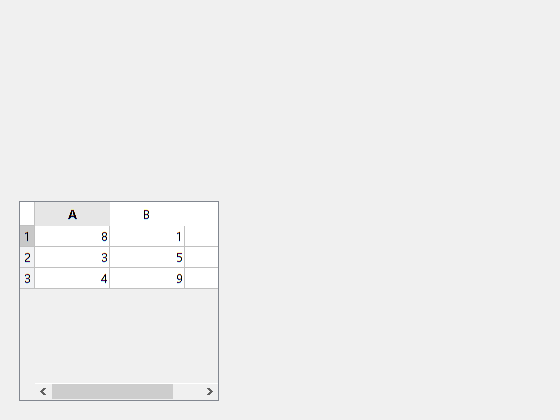

% Java uses its DefaultTableCellRenderer to decide how to 
%   display cell data for the entire table column. 
% If we want to modify cell appearance, 
%   we need to modify the specific column's CellRenderer as shown above.
% This requires programming a Java class.

% In some cases, smart MATLAB programming can save this Java programming: 
%   A CSSM user once requested to know 
%   how to set the number of displayed decimal places.
% The textbook approach would be to create a dedicated CellRenderer. 

% However, in practice, it is easier to preformat the data 
%   using sprintf than to create a separate CellRenderer Java class. 
% The data will then be stored (and sorted) as strings rather than as numbers.
% So, the trick was to populate the field with str2double(sprintf('%.Of', myData))
%   or to cast the data as integers (uint8(myData)) 
%   in order to prevent showing any decimals. 

% While HTML content provides very easy and simple font customization, 
%   greater control can be achieved 
%   by using com.jidesoft.grid.StyledTableCellRenderer 
%   as the table column's cell renderer 
%   (StyledTableCellRenderer extends JIDE's StyledLabel, 
%    which is described in Section 5.5.1). 

% There are similar renderers for trees and lists. 
% A different renderer, which I have called ColoredFieldCellRenderer, 
%   can be used to set a specific color (and/or tooltip) for specific table cells. 

clf;
mtable = uitable('v0');

jtable = mtable.getTable;

data = mat2cell(magic(3) , [1,1,1] , [1,1,1] ) ;  % {8,1,6; 3,5,7; 4,9,2} 
cols = {'<html><b>A' , 'B' , 'C'};
jtable.setModel(javax.swing.table.DefaultTableModel(data,cols));

cr =  javax.swing.table.DefaultTableCellRenderer;

Undefined function or variable 'ColoredFieldCellRenderer'.

jtable.getColumnModel.getColumn(1).setCellRenderer(cr); 
cr.setCellBgColor(0,1,java.awt.Color.cyan); 
cr.setCellTooltip(2,1,'cell-specific tooltip'); 
jtable.repaint; 

% A related common need is to set a nonstandard CellEditor:
%   uitable automatically detects Boolean (islogical) and 
%   Combo-Box (iscell) data columns and uses corresponding cell editors for them 
%   — checkboxes and drop-downs, respectively. 
% For all other data types, uitable uses a standard text-field editor 
%  (javax.swing.DefaultCellEditor25 initialized with JTextField). 

% We often need a color editor or some other nonstandard editors.
% Such nonstandard cell editors cannot be set
%   using the standard MATLAB (mtable) object, 
%   but they can relatively easily be set at the Java (jtable) level, 
%   using one of several options: 
%   - Prepare a Java class that extends DefaultTableCellEditor. 
%   - Prepare a Java class that extends JComboBox, JCheckBox, or JTextField. 
%   - Use JComboBox or a similar editable Java component. 

% The usage in MATLAB is very simple.
% For example, to set the leftmost table column (#0) to 
%   use a combo-box (drop-down) editor, we will use a simple JComboBox: 

clf;
mtable = uitable('v0');
jtable = mtable.getTable;

data = mat2cell(magic(3) , [1,1,1] , [1,1,1] ) ;  % {8,1,6; 3,5,7; 4,9,2} 
cols = {'<html><b>A' , 'B' , 'C'};
jtable.setModel(javax.swing.table.DefaultTableModel(data,cols));

comboBox = javax.swing.JComboBox({'First', 'Last'}) ; 
comboBox.setEditable(true);
editor = javax.swing.DefaultCellEditor(comboBox);
jtable.getColumnModel.getColumn(0).setCellEditor(editor);

% Note how the cell editor (in this case, a combo-box) only appears 
%   for the currently edited cell 
%   — all the other cells appear as defined by their cell renderers 
%   (which in this case is a simple label and not a combo-box). 

% This was not a very powerful example. 
% After all, the drop-down values are static for the entire column.
% It is useful for cases where the same editor component 
%   (e.g., font/color/file selection, etc.) can be used for all data rows. 

% Let us now demonstrate a more realistic and more powerful example: 
%   Very often, the cell drop-down values should depend on its specific row 
%     (i.e., not all column cells should have the same drop-down options). 

% For example, a list of selectable dishes in column B might
%   depend on the dish type in column A. 
% Different table rows will have different dish types and different selectable dishes

% To implement our dish-type example, we need a custom CellEditor Java class. 
% Preparation of a custom CellEditor is beyond the scope of this book 
%   — users are referred to the official documentation
%     or any good text about Java Swing. 
% Here is a simple skeleton of a sample DefaultCellEditor-derived class 
%   for our dish-types example: 
%   it uses a lookup value in the Dish-type column 
%   to set the drop-down values of the Dish column, separately for each row: 
% ... (Omitted)

% 4.1.2 Table Callbacks 

% The new version of uitable supports 
%   CellEditCallback (invoked when a table cell has changed), 
%   CellSelectionCallback (when a cell is selected), 
%   KeyPressFcn (when a keyboard key has been clicked), and 
%   ButtonDownFcn (when the mouse is clicked). 

% In these callbacks, the EventData input parameter 
%   includes the relevant information in a MATLAB struct. 
% This data includes cell indices [row,col], new/previous data, clicked key etc. 
%   (depending on the callback, 
%    some of the information may not be presented). 

% In our callback function, 
%   we need to prevent re-entry if the callback function is not reentrant. 
% For example, if the callback function checks the modified data 
%   and restores the old value in case of an invalid entry, 
%   the function needs to exit immediately when invoked 
%   due to the old value restoration. 
% This can be done by setting some persistent value; as shown below 
%   using the old uitable (adaptation to the new version is easy): 

% ...

% Note that while this approach is simple and easily integrates
%   within the MATLAB program, it cannot handle very rapid data-change events. 
% At some point, when the event queue is overloaded,
%   some callback events will get discarded. 

% A simple solution is to temporarily disable the table object 
%   during callback processing, thus preventing concurrent updates. 

% Alternately, temporarily disable the callback itself
%   when updating rapidly changing table data.
% Both of these solutions can be done in pure MATLAB.

% A more complex solution, suggested by a CSSM poster,
%   is to temporarily disable the JTable MATLAB listeners using Java 
%   or to set up a Java callback method rather than setting up a MATLAB one.
% These later approaches require Java knowledge and 
%   are advanced beyond the scope of this text. 

% The jtable object reference handle exposes all the standard Swing callbacks 
%   specified in Chapter3.
% Inaddition, JTable exposes two additional callbacks:
%   CaretPositionChangedCallback and InputMethodTextChangedCallback. 
% These callbacks correspond to events that are supposed to be raised
%   when the component's input caret position or content has changed,
%   but apparently they are disconnected in MATLAB for some unknown reason. 


% 4.1.3 Customizing Scrollbars, Column Widths, and Selection Behavior 
% A common action that many users need is 
%   controlling the scrollability of the table, 
%   vertically and/or horizontally. 
% This can be done using code similar to the following: 

mtable = uitable;
% jscroll=mtable.TableScrollPane; % old uitable 
jscroll = findjobj(mtable); % new uitable 
jscroll.setVerticalScrollBarPolicy(jscroll.VERTICAL_SCROLLBAR_AS_NEEDED); 
jscroll.setHorizontalScrollBarPolicy(jscroll.HORIZONTAL_SCROLLBAR_AS_NEEDED); 

% The possible scrollbar policies are 
%   *_SCROLLBAR_AS_NEEDED, *_SCROLLBAR_ALWAYS, and *_SCROLLBAR_NEVER.
% These policies are pretty much self-explanatory. 

% Horizontal scrolling policy is normally accompanied 
%   by setting the column auto-resize policy. 
% This affects the interaction between the horizontal scrollbar 
%   and the column widths when the column widths are 
%   modified interactively (by dragging the column header boundary) 
%   or programmatically (see below). 
% Possible auto-resize policy values are 
%   AUTO_RESIZE_ALL_COLUMNS, AUTO_RESIZE_LAST_COLUMN, 
%   AUTO_RESIZE_NEXT_COLUMN, AUTO_RESIZE_SUBSEQUENT_COLUMNS, and AUTO_RESIZE_OFF.
% They are best understood by modifying the AutoResizeMode property 
%   then dragging a column header boundary sideways and checking the effect 
%   on the other columns and on the scrollbar: 

%  ... (Lots of Omitted)

% 4.1.4 Data Sorting and Filtering 

% The new (R2008a+) uitable is based on com.jidesoft.grid.SortableTable 
%   and so has built-in sorting support 
%   — all we need to do is to turn it on 
%  (note: the MATLAB handle has a hidden Sortable property, 
%   but it has no effect — use the Java property instead): 

mtable = uitable('v0');
jtable = mtable.getTable

data = mat2cell(magic(3) , [1,1,1] , [1,1,1] ) ;  % {8,1,6; 3,5,7; 4,9,2} 
cols = {'<html><b>A' , 'B' , 'C'};
jtable.setModel(javax.swing.table.DefaultTableModel(data,cols));

jtable.setSortable(true);
% set(jtable,'Sortable','on'); 
jtable.setAutoResort(true); 
jtable.setMultiColumnSortable(true); 
jtable.setPreserveSelectionsAfterSorting(true); 

% 4.1.5 JIDE Customizations 
% 4.1.6 Controlling Table Structure (Adding/Deleting Rows) 
% 4.1.7 Final Remarks 